Formler at lære udenad

1.1, 1.3, 1.7, 1,12b) og c), 1.12e, 3.19 

simplified steady-flow thermal energy equation:

**Opgave 1.30**

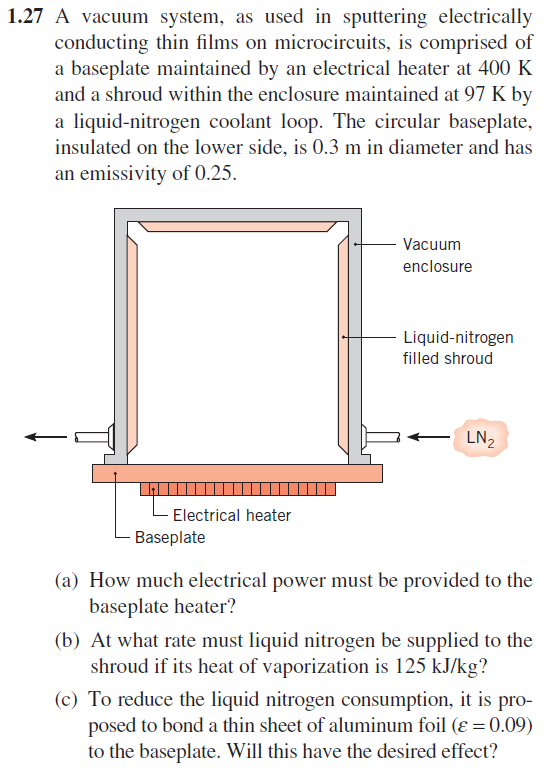

%a
T_heater = 400; %K
T_shroud = 97; %K
d=0.3; %m
epsilon = 0.25; %emesivitet
sigma = 5.67 * 10^-8; % J/K %stefan-boltzman konstant
A = pi*(d/2)^2;
q = A*epsilon * sigma * (T_heater^4 - T_shroud^4)

q = 25.5618


%b
l_f = 125000 %kJ/kg

l_f = 125000

%Q = m*L_f
m_dot = q/l_f %masse stræmmen kg/s

m_dot = 2.0449e-04


m_dot_hours = m_dot * 60 * 60

m_dot_hours = 0.7362

supplie 0,205 gram per s or 0,7362 kg per time

%c
epsilon_alu = 0.09

epsilon_alu = 0.0900

q_alu = q * (epsilon_alu/epsilon) % vi tager og divdere q med epsilon og ganger med epsilon alu istedet.

q_alu = 9.2022


m_dot = q_alu/l_f %masse stræmmen kg/s

m_dot = 7.3618e-05


m_dot_hours = m_dot * 60 * 60

m_dot_hours = 0.2650

**Opgave 1.48**

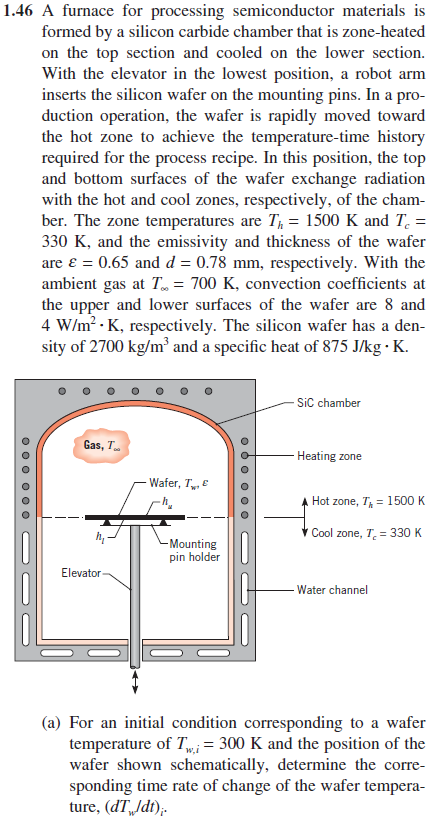

ASSUMPTIONS: 

(1) Wafer temperature is uniform, 

(2) Transient conditions when wafer is initially positioned, 

(3) Hot and cool zones have uniform temperatures, 

(4) Radiation exchange is between small surface (wafer) and large enclosure (chamber, hot or cold zone),

(5) Negligible heat losses from wafer to mounting pin holder.

clear all
T_h = 1500; %K
T_c = 330; %K
epsilon = 0.65; % from wafer
d = 0.78 *1e-3; %thickness of wafer %m
T_amb = 700 %K

T_amb = 700

sigma = 5.67 * 10^-8; % J/K
h_up = 8 % W/m^2*K

h_up = 8

h_low = 4 % W/m^2*K

h_low = 4


rho_SiC = 2700; % kg/m^3
c_p =  875; % J/kg*K

T_wi = 300; %K

q_con_h = h_up * (T_wi - T_amb) %convection above plate

q_con_h = -3200

q_con_l = h_low * (T_wi- T_amb) %convection below plate

q_con_l = -1600

q_rad_h = epsilon * sigma * (T_h^4 - T_wi^4) %radiation above plate

q_rad_h = 1.8628e+05

q_rad_l = epsilon * sigma * (T_c^4 - T_wi^4) %radiation below plate

q_rad_l = 138.5457


q_mark = - q_con_h - q_con_l + q_rad_h + q_rad_l

q_mark = 1.9122e+05

dTdt = q_mark / (rho_SiC * c_p * d)

dTdt = 103.7680

vpa(dTdt, 4)

$$ans = 103.8$$

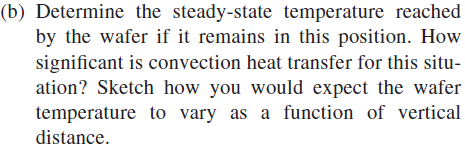

syms T_wi
q_con_h = h_up * (T_wi - T_amb); %convection above plate
q_con_l = h_low * (T_wi- T_amb); %convection below plate
q_rad_h = epsilon * sigma * (T_h^4 - T_wi^4); %radiation above plate
q_rad_l = epsilon * sigma * (T_c^4 - T_wi^4); %radiation below plate
q_mark = - q_con_h - q_con_l + q_rad_h + q_rad_l;
dTdt_eq = 0 == q_mark / (rho_SiC * c_p * d);

T_wi_steady = vpa(solve(dTdt_eq, T_wi),5)

$$T\_wi\_steady = \left(\begin{array}{c} 1250.8\\ 25.003-1276.3\,\mathrm{i}\\ 24.996+1276.3\,\mathrm{i}\\ -1300.8 \end{array}\right)$$

Her bruger vi den reele løsning der er positiv 1251 K

3.28

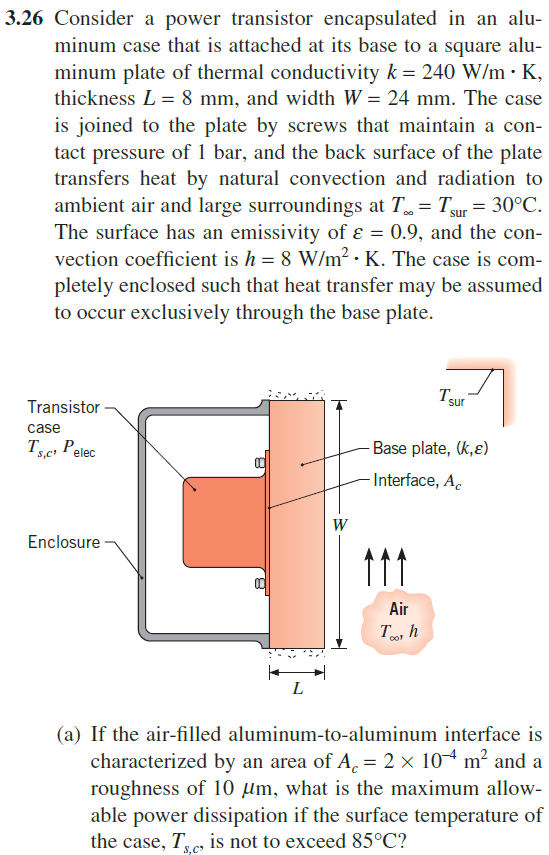

clear all

k = 240; % W/(m*K)
L = 0.008; %m %længde
W = 0.024;%mm
T_inf = 30; %
T_sur = T_inf;
epsilon = 0.9;
h = 8; % W/(M^2 * K) 
A_plate = W^2; % Area of square plate
A_c =2e-4;
mu = 10e-6;
T_sc = 85; %K
sigma = 5.67 * 10^-8; % J/K %stefan-boltzman konstant
R_tc = 2.75; %m^2 * K/ W % Thermal Resistance fra Table 3.1

 * A

 * A

Det antages at varmen spredes instantat til hele højden af pladen og derefter går igennem pladen.

Da vi har steady state er q ens igennem alle modstande.

steady state dT/dt = 0 

syms T_1 T_2 q T_var

T_1 = sym("T_1", "real");
T_2 = sym("T_2", "real");
q = sym("q", "real");

q_saml = (T_sc - T_1)/R_tc

$$q\_saml = \frac{340}{11}-\frac{4\,T_{1}}{11}$$

T_1 = solve(q == q_saml, T_1)

$$T\_1 = 85-\frac{11\,q}{4}$$

q_saml = subs(q_saml, T_1, T_1)

$$q\_saml = \frac{340}{11}-\frac{4\,T_{1}}{11}$$

q_cond = -k*A_plate/L * (T_1 - T_2)

$$q\_cond = \frac{432\,T_{2}}{25}+\frac{1188\,q}{25}-\frac{7344}{5}$$



% T_2_sol = solve(q_conv, T_2)

h_r = epsilon * sigma * (T_2 +T_sur) * (T_2^2 +T_sur^2)

$$h\_r = \left({T_{2}}^{2}+900\right)\,\left(\frac{120491180810419\,T_{2}}{2361183241434822606848}+\frac{1807367712156285}{1180591620717411303424}\right)$$

R1 = R_tc/A_c

R1 = 13750

R2 = L/k *A_plate

R2 = 1.9200e-08

R3_cond = 1/(h*A_plate)

R3_cond = 217.0139

R3_conv = 1/(h_r*A_plate)

$$R3\_conv = \frac{15625}{9\,\left({T_{2}}^{2}+900\right)\,\left(\frac{120491180810419\,T_{2}}{2361183241434822606848}+\frac{1807367712156285}{1180591620717411303424}\right)}$$

R3 = 1/(1/R3_cond + 1/R3_conv)

$$R3 = \frac{1}{\frac{9\,\left({T_{2}}^{2}+900\right)\,\left(\frac{120491180810419\,T_{2}}{2361183241434822606848}+\frac{1807367712156285}{1180591620717411303424}\right)}{15625}+\frac{72}{15625}}$$

q_tot = q == (T_sc - T_inf)/(R1 + R2 + R3)

$$q\_tot = q=\frac{55}{\frac{1}{\frac{9\,\left({T_{2}}^{2}+900\right)\,\left(\frac{120491180810419\,T_{2}}{2361183241434822606848}+\frac{1807367712156285}{1180591620717411303424}\right)}{15625}+\frac{72}{15625}}+\frac{7559142440970555}{549755813888}}$$


T_2 = (T_2 - R_tc)/(R1 + R2) == q_saml + q_cond

$$T\_2 = \frac{549755813888\,T_{2}}{7559142440970555}-\frac{1511828488192}{7559142440970555}=\frac{432\,T_{2}}{25}-\frac{4\,T_{1}}{11}+\frac{1188\,q}{25}-\frac{79084}{55}$$


q_conv = q == h * A_plate * (T_2 - T_inf)

$$q\_conv = q=\left(\frac{4398046511104\,T_{2}}{13123511182240546875}-\frac{1814206280460838736}{13123511182240546875}=\frac{31104\,T_{2}}{390625}-\frac{288\,T_{1}}{171875}+\frac{85536\,q}{390625}-\frac{5812848}{859375}\right)$$

q_rad = q == epsilon * sigma * (T_2^4 - T_sur^4)

$$q\_rad = q=\left(\frac{120491180810419\,{\left(\frac{549755813888\,T_{2}}{7559142440970555}-\frac{1511828488192}{7559142440970555}\right)}^{4}}{2361183241434822606848}-\frac{6099866028527461875}{147573952589676412928}=\frac{120491180810419\,{\left(\frac{4\,T_{1}}{11}-\frac{432\,T_{2}}{25}-\frac{1188\,q}{25}+\frac{79084}{55}\right)}^{4}}{2361183241434822606848}-\frac{6099866028527461875}{147573952589676412928}\right)$$

% q_tot2 = (T_sc - T_inf)/(R1 + R2 + R3)


[q_sol, T_2] = solve([q_tot, T_2_sol], [q, T_2])

Unrecognized function or variable 'T_2_sol'.


% q_fun = matlabFunction(q_tot2, T_2)


% Tss = linspace(T_sur,T_sc,100)

% q_fun = subs(q_tot2, T_2, Tss)
% plot(Tss, q_fun(Tss))
% hold on
% grid('minor')
% yline(double(q_sol(1)), '--')
% yline(double(q_sol(2)), '--')
% yline(double(q_sol(3)), '--')
% yline(double(q_sol(4)), '--')
% xlabel("Temperature (C)")
% ylabel("energi (q)")
% hold off
% [q_sol, T_2_sol, T_1_sol] = solve([q, q_conv, q_cond], [q, T_2, T_1])
% q = 

% [T_1, T_2, q, tam, tamtam] = solve([q_saml, q_cond, q_conv, q_rad, q_tot], [T_1, T_2, q, x, xx])